%% ========================================================================
%  CONTROL CINEMÁTICO DEL CUADRÚPEDO - LEVANTAMIENTO DE PATA
%  ========================================================================
close all; clear; clc;

% Parámetros del robot cuadrúpedo
L0 = 0.2;  % Offset vertical desde la base
L1 = 0.3;  % Longitud primer eslabón
L2 = 0.5;  % Longitud segundo eslabón
L3 = 0.5;  % Longitud tercer eslabón
Lc = 1.0;  % Longitud de la base (en X)
Lb = 0.8;  % Ancho de la base (en Y)

%% ========================================================================
%  FUNCIONES AUXILIARES
%  ========================================================================

%% Función para crear matriz DH estándar
function T = dh_standard(theta, d, a, alpha)
    T = [cos(theta), -sin(theta)*cos(alpha),  sin(theta)*sin(alpha), a*cos(theta);
         sin(theta),  cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta);
         0,           sin(alpha),             cos(alpha),            d;
         0,           0,                      0,                     1];
end

%% Función para matriz de rotación Euler ZYX
function R = euler_zyx(phi, theta, psi)
    Rx = [1, 0, 0;
          0, cos(phi), -sin(phi);
          0, sin(phi), cos(phi)];
    
    Ry = [cos(theta), 0, sin(theta);
          0, 1, 0;
          -sin(theta), 0, cos(theta)];
    
    Rz = [cos(psi), -sin(psi), 0;
          sin(psi), cos(psi), 0;
          0, 0, 1];
    
    R = Rz * Ry * Rx;
end

%% Función matriz antisimétrica (skew-symmetric)
function S = skew(v)
    S = [0, -v(3), v(2);
         v(3), 0, -v(1);
         -v(2), v(1), 0];
end

%% Función para calcular cinemática directa de una pata
function [p_foot, T_b_foot] = leg_forward_kinematics(q1, q2, q3, Tb_0, L1, L2, L3)
    % Cinemática DH de la pata
    T0_1 = dh_standard(q1, 0, L1, -pi/2);
    T1_2 = dh_standard(q2, 0, L2, 0);
    T2_3 = dh_standard(q3, 0, L3, 0);
    T3_f = [0 0 -1 0; -1 0 0 0; 0 1 0 0; 0 0 0 1];
    
    % Transformación desde la base hasta el pie
    T_b_foot = Tb_0 * T0_1 * T1_2 * T2_3 * T3_f;
    
    % Extraer posición del pie
    p_foot = T_b_foot(1:3, 4);
end

%% Función para calcular Jacobiano LINEAL de una pata
function Jv = compute_leg_jacobian_linear(q1, q2, q3, Tb_0, p_base, R_base, L1, L2, L3, leg_index)
    % Calcula el Jacobiano lineal de velocidad de una pata
    % Jv ∈ R^(3x18)
    
    % Posición del pie en el marco del mundo
    [p_foot_base, ~] = leg_forward_kinematics(q1, q2, q3, Tb_0, L1, L2, L3);
    p_foot = p_base + R_base * p_foot_base;
    
    % Jacobiano en el marco de la base (solo articulaciones)
    % Calculamos numéricamente usando diferencias finitas
    epsilon = 1e-6;
    bJv = zeros(3, 3);  % Jacobiano local (3 articulaciones)
    
    for i = 1:3
        q_perturb = [q1, q2, q3];
        q_perturb(i) = q_perturb(i) + epsilon;
        
        [p_pert, ~] = leg_forward_kinematics(q_perturb(1), q_perturb(2), q_perturb(3), Tb_0, L1, L2, L3);
        
        bJv(:, i) = (p_pert - p_foot_base) / epsilon;
    end
    
    % Jacobiano completo en el mundo (18 DOF)
    Jv = zeros(3, 18);
    
    % Columnas 1-3: efecto de velocidad lineal de la base
    Jv(:, 1:3) = eye(3);
    
    % Columnas 4-6: efecto de velocidad angular de la base
    Jv(:, 4:6) = -skew(p_foot - p_base);
    
    % Columnas 7-18: efecto de articulaciones actuadas
    % Solo las 3 articulaciones de esta pata tienen efecto
    start_col = 7 + (leg_index - 1) * 3;
    Jv(:, start_col:start_col+2) = R_base * bJv;
    
end

%% Función para generar trayectoria parabólica
function [p_traj, v_traj] = parabolic_trajectory(p_start, p_end, height, t, T_total)
    % Genera una trayectoria parabólica en 3D
    % p_start: posición inicial [x, y, z]
    % p_end: posición final [x, y, z]
    % height: altura máxima del arco
    % t: tiempo actual
    % T_total: tiempo total de la trayectoria
    
    % Parámetro normalizado
    s = t / T_total;
    s = max(0, min(1, s));  % Clamp entre [0, 1]
    
    % Interpolación lineal en x, y
    p_xy = p_start(1:2) + s * (p_end(1:2) - p_start(1:2));
    
    % Trayectoria parabólica en z
    z = p_start(3) + 4 * height * s * (1 - s) + s * (p_end(3) - p_start(3));
    
    % Posición
    p_traj = [p_xy; z];
    
    % Velocidad (derivada)
    if T_total > 0
        v_xy = (p_end(1:2) - p_start(1:2)) / T_total;
        v_z = (4 * height * (1 - 2*s) + (p_end(3) - p_start(3))) / T_total;
        v_traj = [v_xy; v_z];
    else
        v_traj = zeros(3, 1);
    end
end

%% ========================================================================
%  CONFIGURACIÓN INICIAL
%  ========================================================================

% Posición inicial de la base
xb0 = 0; yb0 = 0; zb0 = 1.4;
phi0 = 0; theta0 = 0; psi0 = 0;

% Configuración articular inicial (todas las patas en configuración similar)
q_init = [
    0,    pi/4,  -pi/2;   % Pata 1 (FD)
    0,    pi/4,  -pi/2;   % Pata 2 (FI)
    0,    pi/4,  -pi/2;   % Pata 3 (TD)
    0,    pi/4,  -pi/2    % Pata 4 (TI)
];

% Vector de configuración completo inicial
q0 = [xb0; yb0; zb0; phi0; theta0; psi0; reshape(q_init', [], 1)];

%% Calcular posiciones iniciales de los pies
R_base0 = euler_zyx(phi0, theta0, psi0);
p_base0 = q0(1:3);

Tb_0_legs = cell(4, 1);
Tb_0_legs{1} = [0 0 1 Lc/2; 0 1 0 Lb/2; -1 0 0 -L0; 0 0 0 1];
Tb_0_legs{2} = [0 0 1 Lc/2; 0 1 0 -Lb/2; -1 0 0 -L0; 0 0 0 1];
Tb_0_legs{3} = [0 0 1 -Lc/2; 0 1 0 Lb/2; -1 0 0 -L0; 0 0 0 1];
Tb_0_legs{4} = [0 0 1 -Lc/2; 0 1 0 -Lb/2; -1 0 0 -L0; 0 0 0 1];

% Posiciones iniciales de los pies en el mundo
p_feet_init = zeros(3, 4);
for i = 1:4
    q_leg = q_init(i, :);
    [p_foot_base, ~] = leg_forward_kinematics(q_leg(1), q_leg(2), q_leg(3), ...
                                               Tb_0_legs{i}, L1, L2, L3);
    p_feet_init(:, i) = p_base0 + R_base0 * p_foot_base;
end

fprintf('Posiciones iniciales de los pies:\n');

Posiciones iniciales de los pies:


for i = 1:4
    fprintf('Pata %d: [%.3f, %.3f, %.3f]\n', i, p_feet_init(1,i), p_feet_init(2,i), p_feet_init(3,i));
end

Pata 1: [0.500, 0.400, 0.193]
Pata 2: [0.500, -0.400, 0.193]
Pata 3: [-0.500, 0.400, 0.193]
Pata 4: [-0.500, -0.400, 0.193]



%% ========================================================================
%  DEFINICIÓN DE TRAYECTORIA PARA PATA 1
%  ========================================================================

% Pata 1 se levanta y vuelve a bajar
p_foot1_start = p_feet_init(:, 1);
p_foot1_end = p_foot1_start + [0.3; 0; 0];  % Se mueve 30cm hacia adelante
arc_height = 0.4;  % Altura del arco: 40 cm

% Tiempo de simulación
T_total = 5.0;  % 5 segundos para completar la trayectoria
dt = 0.01;      % Paso de integración: 10 ms
time = 0:dt:T_total;
N_steps = length(time);

% Parámetros de control
lambda2 = 5.0;  % Ganancia proporcional para tarea 2 (ajustar según respuesta)

%% ========================================================================
%  INICIALIZACIÓN DE VARIABLES
%  ========================================================================

% Almacenar configuración en cada paso
q_history = zeros(18, N_steps);
q_history(:, 1) = q0;

% Almacenar posiciones de los pies
p_feet_history = zeros(3, 4, N_steps);
p_feet_history(:, :, 1) = p_feet_init;

% Almacenar error
error_foot1 = zeros(1, N_steps);

%% ========================================================================
%  BUCLE DE CONTROL
%  ========================================================================

fprintf('\n=== Iniciando simulación de control cinemático ===\n');


=== Iniciando simulación de control cinemático ===



for k = 1:N_steps-1
    
    % Tiempo actual
    t = time(k);
    
    % Configuración actual
    q = q_history(:, k);
    
    % Extraer estado de la base
    p_base = q(1:3);
    phi = q(4); theta = q(5); psi = q(6);
    R_base = euler_zyx(phi, theta, psi);
    
    % Extraer configuración articular
    q_legs = reshape(q(7:18), 3, 4)';
    
    % ====================================================================
    % TAREA 2: TRAYECTORIA DESEADA PARA PATA 1
    % ====================================================================
    [p_foot1_desired, v_foot1_feedforward] = parabolic_trajectory(p_foot1_start, ...
                                                                    p_foot1_end, ...
                                                                    arc_height, t, T_total);
    
    % Posición actual del pie 1
    [p_foot1_base, ~] = leg_forward_kinematics(q_legs(1,1), q_legs(1,2), q_legs(1,3), ...
                                                Tb_0_legs{1}, L1, L2, L3);
    p_foot1_actual = p_base + R_base * p_foot1_base;
    
    % Error de posición
    e2 = p_foot1_actual - p_foot1_desired;
    error_foot1(k) = norm(e2);
    
    % Velocidad deseada (feedforward + feedback)
    x_dot2_desired = v_foot1_feedforward - lambda2 * e2;
    
    % ====================================================================
    % CÁLCULO DE JACOBIANOS
    % ====================================================================
    
    % Jacobiano de Tarea 1: Patas 2, 3, 4 fijas (9x18)
    J1 = zeros(9, 18);
    for i = 2:4
        row_start = (i-2)*3 + 1;
        J1(row_start:row_start+2, :) = compute_leg_jacobian_linear(q_legs(i,1), q_legs(i,2), q_legs(i,3), ...
                                                                     Tb_0_legs{i}, p_base, R_base, ...
                                                                     L1, L2, L3, i);
    end
    
    % Jacobiano de Tarea 2: Pata 1 móvil (3x18)
    J2 = compute_leg_jacobian_linear(q_legs(1,1), q_legs(1,2), q_legs(1,3), ...
                                      Tb_0_legs{1}, p_base, R_base, ...
                                      L1, L2, L3, 1);
    
    % ====================================================================
    % PROYECCIÓN AL ESPACIO NULO
    % ====================================================================
    
    % Pseudoinversa de J1 (Moore-Penrose)
    J1_pinv = J1' / (J1 * J1' + 1e-6 * eye(9));  % Añadimos regularización
    
    % Proyector al espacio nulo de J1
    P1 = eye(18) - J1_pinv * J1;
    
    % Jacobiano aumentado de tarea 2
    J2_bar = J2 * P1;
    
    % Pseudoinversa del Jacobiano aumentado
    J2_bar_pinv = J2_bar' / (J2_bar * J2_bar' + 1e-6 * eye(3));
    
    % ====================================================================
    % CÁLCULO DE VELOCIDADES GENERALIZADAS
    % ====================================================================
    
    % Velocidad deseada de tarea 1 (patas fijas)
    x_dot1_desired = zeros(9, 1);
    
    % Solución jerárquica
    upsilon = J2_bar_pinv * x_dot2_desired;
    
    % ====================================================================
    % INTEGRACIÓN
    % ====================================================================
    
    % Actualizar configuración
    q_next = q + dt * upsilon;
    
    % Almacenar
    q_history(:, k+1) = q_next;
    
    % Calcular nuevas posiciones de los pies
    p_base_next = q_next(1:3);
    phi_next = q_next(4); theta_next = q_next(5); psi_next = q_next(6);
    R_base_next = euler_zyx(phi_next, theta_next, psi_next);
    q_legs_next = reshape(q_next(7:18), 3, 4)';
    
    for i = 1:4
        [p_foot_base, ~] = leg_forward_kinematics(q_legs_next(i,1), q_legs_next(i,2), q_legs_next(i,3), ...
                                                   Tb_0_legs{i}, L1, L2, L3);
        p_feet_history(:, i, k+1) = p_base_next + R_base_next * p_foot_base;
    end
    
    % Mostrar progreso cada 0.5 segundos
    if mod(k, round(0.5/dt)) == 0
        fprintf('t = %.2f s | Error pata 1: %.4f m | Base: [%.3f, %.3f, %.3f]\n', ...
                t, error_foot1(k), p_base(1), p_base(2), p_base(3));
    end
end

t = 0.49 s | Error pata 1: 0.0006 m | Base: [-0.053, -0.058, 1.430]
t = 0.99 s | Error pata 1: 0.0010 m | Base: [-0.090, -0.099, 1.447]
t = 1.49 s | Error pata 1: 0.0009 m | Base: [-0.109, -0.125, 1.457]
t = 1.99 s | Error pata 1: 0.0005 m | Base: [-0.113, -0.137, 1.462]
t = 2.49 s | Error pata 1: 0.0002 m | Base: [-0.103, -0.138, 1.465]
t = 2.99 s | Error pata 1: 0.0003 m | Base: [-0.082, -0.129, 1.465]
t = 3.49 s | Error pata 1: 0.0003 m | Base: [-0.047, -0.110, 1.462]
t = 3.99 s | Error pata 1: 0.0002 m | Base: [0.002, -0.081, 1.453]
t = 4.49 s | Error pata 1: 0.0014 m | Base: [0.069, -0.042, 1.435]
t = 4.99 s | Error pata 1: 0.0040 m | Base: [0.156, 0.009, 1.402]



fprintf('=== Simulación completada ===\n\n');

=== Simulación completada ===



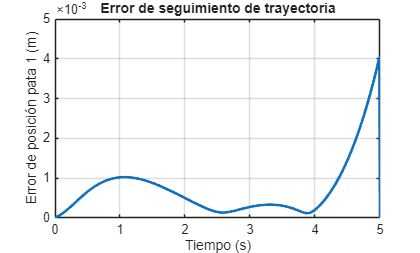


%% ========================================================================
%  VISUALIZACIÓN
%  ========================================================================

% Figura 1: Evolución del error
figure(1);
plot(time, error_foot1, 'LineWidth', 2);
grid on;
xlabel('Tiempo (s)');
ylabel('Error de posición pata 1 (m)');
title('Error de seguimiento de trayectoria');

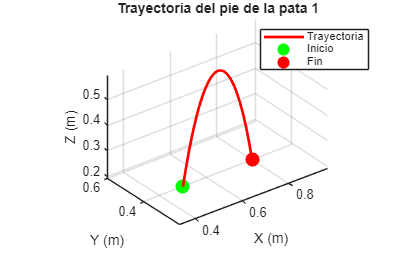


% Figura 2: Trayectoria de la pata 1
figure(2);
hold on; grid on; axis equal;
p1_traj = squeeze(p_feet_history(:, 1, :));
plot3(p1_traj(1, :), p1_traj(2, :), p1_traj(3, :), 'r-', 'LineWidth', 2);
plot3(p1_traj(1, 1), p1_traj(2, 1), p1_traj(3, 1), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
plot3(p1_traj(1, end), p1_traj(2, end), p1_traj(3, end), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
title('Trayectoria del pie de la pata 1');
legend('Trayectoria', 'Inicio', 'Fin');
view(3);

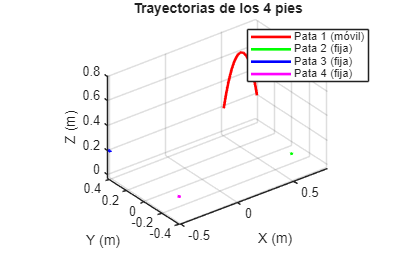


% Figura 3: Trayectorias de todas las patas
figure(3);
hold on; grid on; axis equal;
colors = {'r', 'g', 'b', 'm'};
for i = 1:4
    p_traj = squeeze(p_feet_history(:, i, :));
    plot3(p_traj(1, :), p_traj(2, :), p_traj(3, :), colors{i}, 'LineWidth', 2);
end
xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
title('Trayectorias de los 4 pies');
legend('Pata 1 (móvil)', 'Pata 2 (fija)', 'Pata 3 (fija)', 'Pata 4 (fija)');
view(3);


fprintf('Gráficas generadas.\n');

Gráficas generadas.


%% ========================================================================
%  VISUALIZACIÓN 3D DEL ROBOT
%  ========================================================================

%% Función para dibujar un cubo (base del robot)
function draw_cube(T_wb, Lc, Lb, L0)
    % Vértices del cubo en el marco de la base
    vertices = [
         Lc/2,  Lb/2,  0;      % 1: superior frontal derecha
         Lc/2, -Lb/2,  0;      % 2: superior frontal izquierda
        -Lc/2, -Lb/2,  0;      % 3: superior trasera izquierda
        -Lc/2,  Lb/2,  0;      % 4: superior trasera derecha
         Lc/2,  Lb/2, -L0;     % 5: inferior frontal derecha
         Lc/2, -Lb/2, -L0;     % 6: inferior frontal izquierda
        -Lc/2, -Lb/2, -L0;     % 7: inferior trasera izquierda
        -Lc/2,  Lb/2, -L0      % 8: inferior trasera derecha
    ];
    
    % Transformar vértices al marco del mundo
    vertices_world = zeros(8, 3);
    for i = 1:8
        p = [vertices(i, :), 1]';
        p_w = T_wb * p;
        vertices_world(i, :) = p_w(1:3)';
    end
    
    % Definir las 6 caras del cubo
    faces = [
        1, 2, 6, 5;  % Cara frontal (X+)
        3, 4, 8, 7;  % Cara trasera (X-)
        1, 4, 8, 5;  % Cara derecha (Y+)
        2, 3, 7, 6;  % Cara izquierda (Y-)
        1, 2, 3, 4;  % Cara superior (Z = 0)
        5, 6, 7, 8   % Cara inferior (Z = -L0)
    ];
    
    % Dibujar el cubo con caras sólidas
    patch('Vertices', vertices_world, 'Faces', faces, ...
          'FaceColor', [0.7 0.7 0.7], 'FaceAlpha', 0.8, ...
          'EdgeColor', 'k', 'LineWidth', 1.5);
end

%% Función para dibujar el robot completo en un instante
function draw_robot_frame(q, L0, L1, L2, L3, Lc, Lb, show_axes)
    % q: configuración [xb, yb, zb, phi, theta, psi, q1...q12]
    % show_axes: true/false para mostrar ejes de coordenadas
    
    % Extraer estado de la base
    p_base = q(1:3);
    phi = q(4); theta = q(5); psi = q(6);
    R_base = euler_zyx(phi, theta, psi);
    
    % Matriz de transformación de la base
    T_wb = eye(4);
    T_wb(1:3, 1:3) = R_base;
    T_wb(1:3, 4) = p_base;
    
    % Dibujar la base como cubo sólido
    draw_cube(T_wb, Lc, Lb, L0);
    
    % Dibujar ejes de la base (opcional)
    if show_axes
        axis_length = 0.3;
        origin_base = T_wb * [0; 0; 0; 1];
        x_axis = T_wb * [axis_length; 0; 0; 1];
        y_axis = T_wb * [0; axis_length; 0; 1];
        z_axis = T_wb * [0; 0; axis_length; 1];
        
        plot3([origin_base(1), x_axis(1)], [origin_base(2), x_axis(2)], ...
              [origin_base(3), x_axis(3)], 'r-', 'LineWidth', 2);
        plot3([origin_base(1), y_axis(1)], [origin_base(2), y_axis(2)], ...
              [origin_base(3), y_axis(3)], 'g-', 'LineWidth', 2);
        plot3([origin_base(1), z_axis(1)], [origin_base(2), z_axis(2)], ...
              [origin_base(3), z_axis(3)], 'b-', 'LineWidth', 2);
    end
    
    % Transformaciones de la base a cada pata
    Tb_0_legs = cell(4, 1);
    Tb_0_legs{1} = [0 0 1 Lc/2; 0 1 0 Lb/2; -1 0 0 -L0; 0 0 0 1];
    Tb_0_legs{2} = [0 0 1 Lc/2; 0 1 0 -Lb/2; -1 0 0 -L0; 0 0 0 1];
    Tb_0_legs{3} = [0 0 1 -Lc/2; 0 1 0 Lb/2; -1 0 0 -L0; 0 0 0 1];
    Tb_0_legs{4} = [0 0 1 -Lc/2; 0 1 0 -Lb/2; -1 0 0 -L0; 0 0 0 1];
    
    % Colores para cada pata
    colors = {[1 0 0], [0 0.7 0], [0 0 1], [1 0.5 0]};
    
    % Extraer configuración articular
    q_legs = reshape(q(7:18), 3, 4)';
    
    % Dibujar cada pata
    for leg = 1:4
        q1 = q_legs(leg, 1);
        q2 = q_legs(leg, 2);
        q3 = q_legs(leg, 3);
        
        % Cinemática de la pata
        T_b0 = Tb_0_legs{leg};
        
        T01 = dh_standard(q1, 0, L1, -pi/2);
        T12 = dh_standard(q2, 0, L2, 0);
        T23 = dh_standard(q3, 0, L3, 0);
        T3f = [0 0 -1 0; -1 0 0 0; 0 1 0 0; 0 0 0 1];
        
        % Posiciones de las articulaciones en el marco de la base
        P0 = T_b0 * [0; 0; 0; 1];
        P1 = T_b0 * T01 * [0; 0; 0; 1];
        P2 = T_b0 * T01 * T12 * [0; 0; 0; 1];
        P3 = T_b0 * T01 * T12 * T23 * [0; 0; 0; 1];
        Pf = T_b0 * T01 * T12 * T23 * T3f * [0; 0; 0; 1];
        
        % Transformar al mundo
        P0_w = T_wb * P0;
        P1_w = T_wb * P1;
        P2_w = T_wb * P2;
        P3_w = T_wb * P3;
        Pf_w = T_wb * Pf;
        
        % Dibujar eslabones
        plot3([P0_w(1), P1_w(1)], [P0_w(2), P1_w(2)], [P0_w(3), P1_w(3)], ...
              'Color', colors{leg}, 'LineWidth', 3);
        plot3([P1_w(1), P2_w(1)], [P1_w(2), P2_w(2)], [P1_w(3), P2_w(3)], ...
              'Color', colors{leg}, 'LineWidth', 3);
        plot3([P2_w(1), P3_w(1)], [P2_w(2), P3_w(2)], [P2_w(3), P3_w(3)], ...
              'Color', colors{leg}, 'LineWidth', 3);
        plot3([P3_w(1), Pf_w(1)], [P3_w(2), Pf_w(2)], [P3_w(3), Pf_w(3)], ...
              'Color', colors{leg}, 'LineWidth', 3);
        
        % Marcar articulaciones
        plot3(P1_w(1), P1_w(2), P1_w(3), 'ko', 'MarkerSize', 6, 'MarkerFaceColor', 'k');
        plot3(P2_w(1), P2_w(2), P2_w(3), 'ko', 'MarkerSize', 6, 'MarkerFaceColor', 'k');
        plot3(P3_w(1), P3_w(2), P3_w(3), 'ko', 'MarkerSize', 6, 'MarkerFaceColor', 'k');
        plot3(Pf_w(1), Pf_w(2), Pf_w(3), 'o', 'MarkerSize', 10, ...
              'MarkerFaceColor', colors{leg}, 'MarkerEdgeColor', 'k', 'LineWidth', 2);
    end
end

%% ========================================================================
%  ANIMACIÓN DEL ROBOT
%  ========================================================================

fprintf('\n=== Generando animación 3D ===\n');


=== Generando animación 3D ===


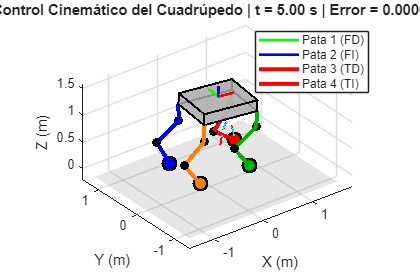


% Crear figura para animación
fig_anim = figure(4);
set(fig_anim, 'Position', [100, 100, 1200, 800]);

% Decidir cuántos frames mostrar (para no hacerlo muy lento)
frame_skip = round(0.05 / dt);  % Mostrar cada 50 ms
indices = 1:frame_skip:N_steps;

% Límites de la visualización
all_positions = reshape(p_feet_history, 3, []);
x_min = min(all_positions(1,:)) - 1;
x_max = max(all_positions(1,:)) + 1;
y_min = min(all_positions(2,:)) - 1;
y_max = max(all_positions(2,:)) + 1;
z_min = -0.2;
z_max = max(all_positions(3,:)) + 1;

% Crear video (opcional)
create_video = true;  % Cambiar a true si quieres guardar video
if create_video
    video_writer = VideoWriter('quadruped_motion.avi');
    video_writer.FrameRate = 20;
    open(video_writer);
end

for idx = 1:length(indices)
    k = indices(idx);
    t = time(k);
    
    clf;
    hold on; grid on; axis equal;
    
    % Configurar ejes
    xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
    xlim([x_min, x_max]);
    ylim([y_min, y_max]);
    zlim([z_min, z_max]);
    view(3);
    
    % Dibujar plano del suelo
    [X_ground, Y_ground] = meshgrid(x_min:0.5:x_max, y_min:0.5:y_max);
    Z_ground = zeros(size(X_ground));
    surf(X_ground, Y_ground, Z_ground, 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'FaceColor', [0.5 0.5 0.5]);
    
    % Dibujar el robot
    draw_robot_frame(q_history(:, k), L0, L1, L2, L3, Lc, Lb, true);
    
    % Dibujar trayectoria de la pata 1 hasta el momento actual
    p1_traj_so_far = squeeze(p_feet_history(:, 1, 1:k));
    plot3(p1_traj_so_far(1, :), p1_traj_so_far(2, :), p1_traj_so_far(3, :), ...
          'r--', 'LineWidth', 1.5);
    
    % Dibujar trayectoria deseada completa
    t_traj = linspace(0, T_total, 100);
    p_desired_full = zeros(3, 100);
    for i = 1:100
        [p_des, ~] = parabolic_trajectory(p_foot1_start, p_foot1_end, arc_height, t_traj(i), T_total);
        p_desired_full(:, i) = p_des;
    end
    plot3(p_desired_full(1, :), p_desired_full(2, :), p_desired_full(3, :), ...
          'c--', 'LineWidth', 1, 'DisplayName', 'Trayectoria deseada');
    
    % Título con información
    title(sprintf('Control Cinemático del Cuadrúpedo | t = %.2f s | Error = %.4f m', ...
                  t, error_foot1(k)));
    
    legend('', '', '', 'Pata 1 (FD)', 'Pata 2 (FI)', 'Pata 3 (TD)', 'Pata 4 (TI)', ...
           'Location', 'northeast');
    
    drawnow;
    
    % Guardar frame si se está creando video
    if create_video
        frame = getframe(gcf);
        writeVideo(video_writer, frame);
    end
    
    % Pequeña pausa para visualización suave
    pause(0.01);
end


if create_video
    close(video_writer);
    fprintf('Video guardado como: quadruped_motion.avi\n');
end

Video guardado como: quadruped_motion.avi



fprintf('=== Animación completada ===\n');

=== Animación completada ===


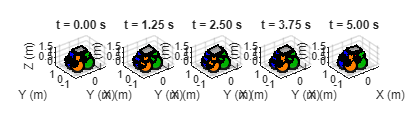


%% ========================================================================
%  VISUALIZACIÓN DE CONFIGURACIONES CLAVE
%  ========================================================================

% Figura 5: Comparación en momentos clave
figure(5);
set(gcf, 'Position', [100, 100, 1800, 500]);

key_times = [0, T_total/4, T_total/2, 3*T_total/4, T_total];
key_indices = round(key_times / dt) + 1;
key_indices(key_indices > N_steps) = N_steps;

for i = 1:length(key_times)
    subplot(1, 5, i);
    hold on; grid on; axis equal;
    
    xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
    xlim([x_min, x_max]);
    ylim([y_min, y_max]);
    zlim([z_min, z_max]);
    view(3);
    
    % Plano del suelo
    [X_ground, Y_ground] = meshgrid(x_min:0.5:x_max, y_min:0.5:y_max);
    Z_ground = zeros(size(X_ground));
    surf(X_ground, Y_ground, Z_ground, 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'FaceColor', [0.5 0.5 0.5]);
    
    % Dibujar robot
    draw_robot_frame(q_history(:, key_indices(i)), L0, L1, L2, L3, Lc, Lb, false);
    
    title(sprintf('t = %.2f s', key_times(i)));
end


fprintf('Visualización completada.\n\n');

Visualización completada.




%% ========================================================================
%  ANÁLISIS DE RESULTADOS
%  ========================================================================

fprintf('=== ANÁLISIS DE RESULTADOS ===\n');

=== ANÁLISIS DE RESULTADOS ===


fprintf('Error máximo: %.4f m\n', max(error_foot1));

Error máximo: 0.0040 m


fprintf('Error final: %.4f m\n', error_foot1(end));

Error final: 0.0000 m


fprintf('Error promedio: %.4f m\n', mean(error_foot1));

Error promedio: 0.0007 m



% Verificar que las patas 2, 3, 4 se mantuvieron fijas
fprintf('\nDesplazamiento de patas fijas:\n');


Desplazamiento de patas fijas:


for i = 2:4
    displacement = norm(p_feet_history(:, i, end) - p_feet_history(:, i, 1));
    fprintf('Pata %d: %.6f m\n', i, displacement);
end

Pata 2: 0.021975 m
Pata 3: 0.022734 m
Pata 4: 0.018199 m



% Desplazamiento de la base
base_displacement = norm(q_history(1:3, end) - q_history(1:3, 1));
fprintf('\nDesplazamiento de la base: %.4f m\n', base_displacement);


Desplazamiento de la base: 0.1578 m



% Rotación de la base
base_rotation = norm([q_history(4, end) - q_history(4, 1), ...
                      q_history(5, end) - q_history(5, 1), ...
                      q_history(6, end) - q_history(6, 1)]) * 180/pi;
fprintf('Rotación de la base: %.2f grados\n', base_rotation);

Rotación de la base: 6.73 grados



fprintf('==============================\n');